# Atividade 03_03

Otávio Baziewicz Filho - 1942808

## Clear Workspace

clear all;
close all;
clc;

## Script

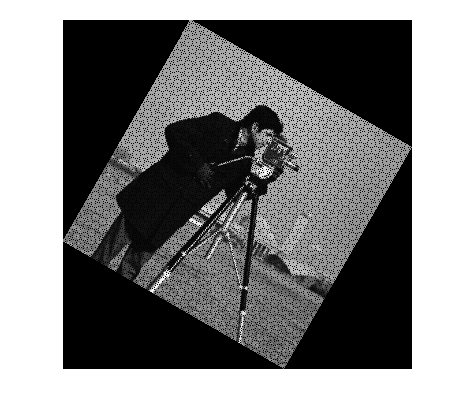

G = imread('cameraman.tif');
nr = size(G,1);
nc = size(G,2);
[X,Y] = meshgrid(1:nr,1:nc);
N = nr*nc;
I = [X(:)';
 Y(:)';
 ones(1,N)];
ang = 30*pi/180;
T = [ cos(ang) sin(ang) 0;
 -sin(ang) cos(ang) 0;
 0 0 1];
K = T*I;
temp1 = min(K, [], 2);
m = repmat(temp1, 1, N);
temp2 = K - m;
Kadj = 1 + floor(temp2);
nrOut = max(Kadj(1,:));
ncOut = max(Kadj(2,:));
Gout = uint8(zeros(nrOut, ncOut));
for k = 1:length(Kadj)
 Gout(Kadj(1,k), Kadj(2,k)) = G(I(1,k), I(2,k));
end
imshow(Gout);

## Problema do fw mapping

Porque aparecem pontos pretos na imagem rotacionada?

**Resposta: **O forwarding mapping é um tipo de transformação geométrica que mapeia os pixels do conjunto de entrada para o conjunto de saída. Nesse cenário é possível que um pixel seja mapeado para um local sobreposto e fazendo com que o seu local de origem esperado fique vazio. Isso gera os "buracos" na imagem.